# First order models and characterisation of the behaviour

This livescript is a brief manual in support of the app ***firstordermodel_response_characterisatioin.mlapp***.   This is a simple interface to understand the modelling and behaviour of simple 1st order models represented in time constant form. Once studetns have grasped the core concepts, it would be reasonable to move on to the following file, ***firstordermodel_behaviour.mlapp*** which tests the ability to estimated time constant and gain using these insights.

More extensive background and instruction on the use of MATLAB can be found in the files: ***firstordermodels_responses_analysis_and_feedback.mlx*** and ***firstordermodels_in_matlab.mlx***.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Engineering context

- Time constant and gain formulation

- Behaviour characterisation and the time constant form

- App file and usage

## 1. Engineering context

We consider a generic first order differential equation model, state ***x***, with a constant input ***f***, for example:


$$a\frac{\textrm{dx}}{\textrm{dt}}+\textrm{bx}=\textrm{cf}$$


For simplicity this file will use $f=1$, and simple scaling can be used to find solutions for other constant values.

## 2. Time constant and gain formulation

As the basic model is a 1st order differential equation, it is common place to model these in time constant form.


$$a\frac{\textrm{dx}}{\textrm{dt}}+\textrm{bx}=\textrm{cf}\;\;\Leftrightarrow \;\;\;\frac{a}{b}\frac{\textrm{dx}}{\textrm{dt}}+x=\frac{c}{b}f\;\;\;\Leftrightarrow \;\;\;\;T\frac{\textrm{dv}}{\textrm{dt}}+v=\textrm{Cf}$$


where $T=\frac{a}{b}$ is the time constant and $C=\frac{c}{b}$ is the steady-state system gain (often just denoted as gain).

Time constant form is useful for understanding behaviours. The generic solution, for constant ***f***, is:


$$\left\lbrace x\left(t\right)=\left\lbrack x\left(0\right)-\textrm{Cf}\right\rbrack e^{-\frac{t}{T}} +\textrm{Cf}\right\rbrace \;\;\Rightarrow \;\;\left\lbrace x\left(T\right)=\left\lbrack x\left(0\right)-\textrm{Cf}\right\rbrack e^{-1} +\textrm{Cf}\right\rbrace \;\;\;$$


## 3. Behaviour characterisation using the time constant form

The time constant *T *gives an indicator of the convergence rate (typically about 3 time constants to be within 5% of steady-state) and the system gain C indicates  the expected steady-state value of the system state (with no disturbances) and  ***f=1 ***(a more generic formula for the steady state is ***Cf***).  Once can show that there are certain invariants in the response wqhich come from the exponential part of the solution above. Specifically consider the following time instants: *t=T, t=2T *and* t=3T*.


$$\left\lbrace x\left(T\right)=\left\lbrack x\left(0\right)-\textrm{Cf}\right\rbrack e^{-\frac{T}{T}} +\textrm{Cf}\right\rbrace \;\;\Rightarrow \;\;\left\lbrace x\left(T\right)=\left\lbrack x\left(0\right)-\textrm{Cf}\right\rbrack e^{-1} +\textrm{Cf}\right\rbrace \;$$

$$=\left\lbrack \textrm{Cf}-x\left(0\right)\right\rbrack 0\ldotp 63+x\left(0\right)$$



$$\left\lbrace x\left(2T\right)=\left\lbrack x\left(0\right)-\textrm{Cf}\right\rbrack e^{-\frac{2T}{T}} +\textrm{Cf}\right\rbrace \;\;\Rightarrow \;\;\left\lbrace x\left(2T\right)=\left\lbrack x\left(0\right)-\textrm{Cf}\right\rbrack e^{-2} +\textrm{Cf}\right\rbrace \;$$

$$=\left\lbrack \textrm{Cf}-x\left(0\right)\right\rbrack 0\ldotp 86+x\left(0\right)$$



$$\left\lbrace x\left(3T\right)=\left\lbrack x\left(0\right)-\textrm{Cf}\right\rbrack e^{-\frac{3T}{T}} +\textrm{Cf}\right\rbrace \;\;\Rightarrow \;\;\left\lbrace x\left(\textrm{eT}\right)=\left\lbrack x\left(0\right)-\textrm{Cf}\right\rbrack e^{-3} +\textrm{Cf}\right\rbrace \;$$

$$=\left\lbrack \textrm{Cf}-x\left(0\right)\right\rbrack 0\ldotp 95+x\left(0\right)$$


In summary:

- In *T* seconds, the response moves 63% of the way from the starting value of *x(0*) to the asymptotic value of *Cf*.

- In 2*T* seconds, the response moves 86% of the way from the starting value of *x(0*) to the asymptotic value of *Cf*.

- In 3*T* seconds, the response moves 95% of the way from the starting value of *x(0*) to the asymptotic value of *Cf*.

These is easily illustrated using some MATLAB code below. Users can change the values for *T, C, x0 *and note the invariance aspects of the corresponding plot (use run section to update).

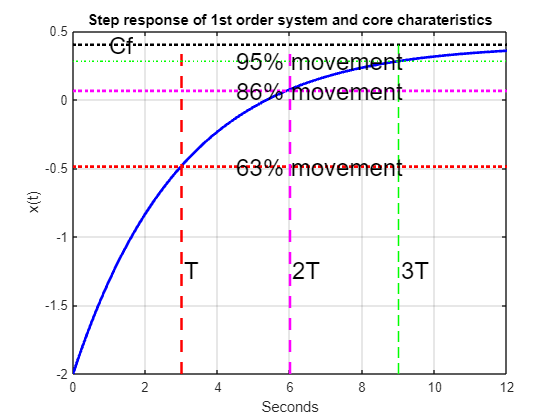

% determine responses (assume f=1)
T=3;
C=0.4;
x0=-2;
t=linspace(0,4*T,101);
x=(x0-C)*exp(-t/T) + C;
x63 = C+(x0-C)*.37;  
x86 =  C+(x0-C)*.14;  
x95 =  C+(x0-C)*.05;  
figure;clf
plot(t,x,'b','linewidth',2); hold on
aa=plot([T,T],[x0,C],'r--',[0,4*T],[x63,x63],'r:',[0,4*T],[C,C],'k:');
bb=plot([2*T,2*T],[x0,C],'m--',[0,4*T],[x86,x86],'m:');
cc=plot([3*T,3*T],[x0,C],'g--',[0,4*T],[x95,x95],'g:');
grid
set(bb,'linewidth',2);
set(aa,'linewidth',2);
xlabel('Seconds')
ylabel('x(t)')
text(T/3,C,'Cf','fontsize',18);
ylim([x0,0.5]);
text(T*1.02,x0+(x63-x0)*0.5,'T','fontsize',18)
text(T*1.5,x63,'63% movement','fontsize',18)
text(T*2.02,x0+(x63-x0)*0.5,'2T','fontsize',18)
text(T*1.5,x86,'86% movement','fontsize',18)
text(T*3.02,x0+(x63-x0)*0.5,'3T','fontsize',18)
text(T*1.5,x95,'95% movement','fontsize',18)
title('Step response of 1st order system and core charateristics')

## 4. App file and usage

The app allows the user to create a range of examples using the sliders. The updated response appears as soon as a slider is changed. Users will be able to observe the invariance and thus the significance of the lines corresponding to  *t=T, t=2T *and* t=3T *and also the importance of 63%, 86% and 95% movement.